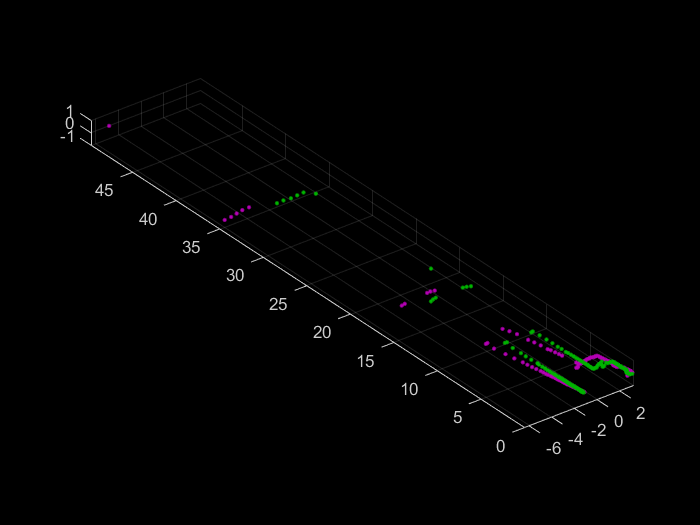

clc;clear;
ply_0 = pcread('3.ply');
ply_1 = pcread('4.ply');
figure;
pcshowpair(ply_0, ply_1, 'MarkerSize', 50);

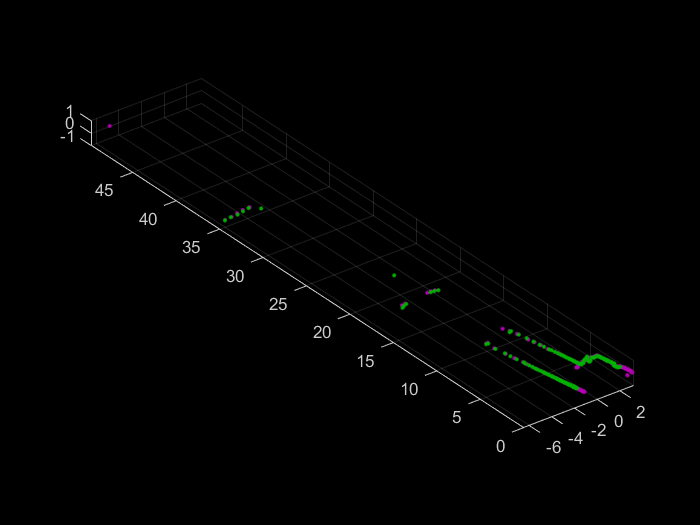

%库函数方法
laser_map = ply_0;
curr_ply = ply_1;
tform_init = affine3d([1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]);
[~, curr_ply] = pcregistericp(curr_ply, laser_map, 'Metric','pointToPoint', 'InitialTransform', tform_init, 'MaxIterations', 100, 'Tolerance', [0.01, 0.001]);
ply_1t = curr_ply;
figure
pcshowpair(ply_0, ply_1t, 'MarkerSize', 50);

goal1 = simple_target_error_goal(curr_ply,laser_map,"PointToPoint")

goal1 = 0.0419

%简单ICP匹配
curr_ply = ply_1;
[~,curr_ply] = myicp(curr_ply, laser_map,"PointToLine","kdtree");

最终迭代次数为200
最终目标函数值为6.2567


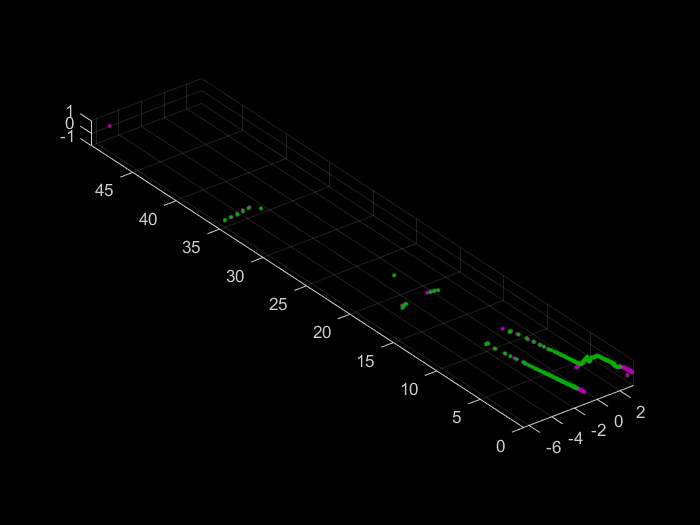

ply_1t = curr_ply;
figure
pcshowpair(ply_0, ply_1t, 'MarkerSize', 50);

goal2 = simple_target_error_goal(curr_ply,laser_map,"PointToPoint")

goal2 = 0.0419

%ransac匹配
curr_ply = ply_1;
[~,curr_ply] = my_ransac_icp(curr_ply, laser_map,"relative");

ransac目标函数值为7.683


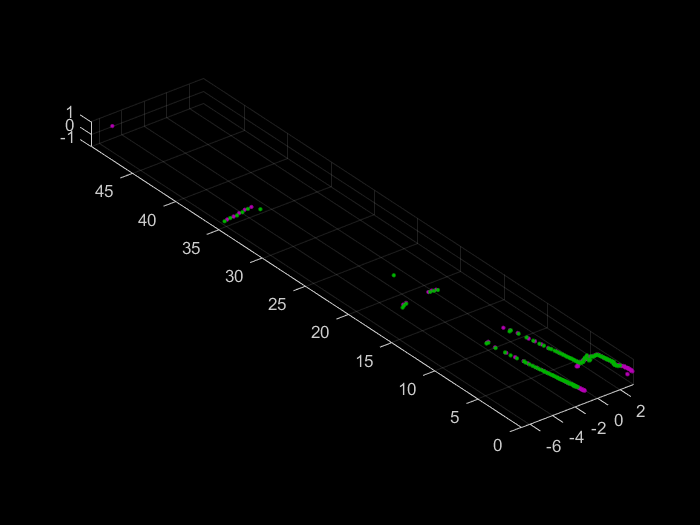

ply_1t = curr_ply;
figure
pcshowpair(ply_0, ply_1t, 'MarkerSize', 50);

goal3 = simple_target_error_goal(curr_ply,laser_map,"PointToPoint")

goal3 = 0.0427